# Geom-SINDy DSI vs SINDy DSI (consider ideal T&N space and non-ideal SINDy with P modify in training) - Set up at 2024May31

#### This is the Euler motion dynamics on torus version.

clear
clc

rng(1)
frontsize=12;


## Initialization

global n% ambient space dimension
global d% manifold dimension
global Xnoise
global Pnum
global index
global Dt

% Pnum=4000*2.5;%number of samples in training set
n=3;% ambient space dimension
d=2;% manifold dimension

mode=2;

## 1 Data set generation

#### Generate sample data set - Spring torus curve

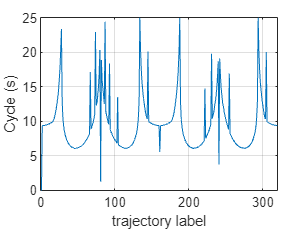

curveNum = 160*2;

R = 1;   % main radius
r = 0.25;   % tube radius
I1=1.6;
I2=1;
I3=0.72;

t_total=25;
dt=1e-4;
t_simu=0:dt:t_total;

DataCloud = cell(1,curveNum); % preallocate cell array


dphi0=2*pi/curveNum;

phi0 = 0:dphi0:2*pi-dphi0;
theta0=zeros(size(phi0));

% test at one special initial point
% phi0 = [2*pi/160*1 2*pi/160*2 2*pi/160*3 2*pi/160*4 2*pi/160*5 2*pi/160*6 2*pi/160*7 2*pi/160*8 2*pi/160*9 2*pi/160*10 2*pi/160*11 2*pi/160*12 2*pi/160*13 2*pi/160*14 2*pi/160*15];
% theta0=[0 0 0 0 0 0 0 0 0 0 0 0 0 0 0];

for curN = 1:curveNum
angle0 = [phi0(curN);theta0(curN)];
tspan=t_simu;
options_ode = odeset('RelTol',1e-10,'AbsTol',1e-10);

% ==========sphere coordinate version=====================
[t_simu, Angle] = ode15s(@(t, angle) torusDynamics_EulerMotion(t,angle,I1,I2,I3,r,R), tspan, angle0);
X = zeros(n, length (t_simu));
x = (R + r * cos(Angle(:, 2))) .* cos(Angle(:, 1));
y = (R + r * cos(Angle(:, 2))) .* sin(Angle(:, 1));
z = r * sin(Angle(:, 2));
X=[x';y';z'];
DataCloud{curN} = X;
end

curvePointsPerCyc=[];
for curN=1:curveNum
    curvePointsPerCyc(curN)=numPointPerCyc(DataCloud{curN},dt);
end

Tcyc=(curvePointsPerCyc-1)*dt;

figure
plot(Tcyc);
grid on
xlabel('trajectory label');ylabel('Cycle (s)')


X_Together=[];
for curN = 1:curveNum
X_Together=[X_Together DataCloud{curN}(:,1:curvePointsPerCyc(curN))];
end
Ptotal=size(X_Together,2);

#### Display

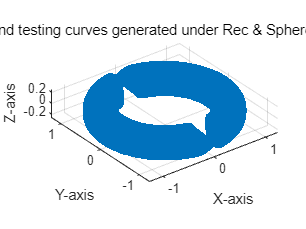

% Plot the manifold in 3D space
figure
% for curN=1:curveNum
% plot3(DataCloud{curN}(1,:),DataCloud{curN}(2,:),DataCloud{curN}(3,:))
% hold on
% end
% hold off
scatter3(X_Together(1,1:5:end),X_Together(2,1:5:end),X_Together(3,1:5:end),'.')
title('training and testing curves generated under Rec & Sphere Coor model')

grid on;
axis equal; % Make sure the aspect ratio is the same for all axes
xlabel('X-axis');
ylabel('Y-axis');
zlabel('Z-axis');

% title('simulate data');

#### Sampling

sp=500;% sampling muliple of simulation rate
Dt=sp*dt;

timeMulti=0.5;

Pnum_fixWin=floor(t_total/dt*timeMulti);% points on each curve 


Xnoise={};
Xsp={};
Xtrain={};
Xtest={};

Pnum=[];

count=1;
for curN=1:curveNum
    if norm(std(DataCloud{curN}, 0, 2))>1e-4 && ismember(curN,[1:round(curveNum/2) round(curveNum*7/12:curveNum*11/12)])
    Xsp{count}=DataCloud{curN}(:,1:sp:curvePointsPerCyc(curN));
    Pnum(count)=size(Xsp{count},2);
    
    Xsp_fixWin{count}=DataCloud{curN}(:,1:sp:Pnum_fixWin);

    count=count+1;
    end
end
curveNumNoSglP=size(Xsp,2);

trainIndex=1:2:curveNumNoSglP;
testIndex=2:2:curveNumNoSglP;

Xtrain=Xsp(1,trainIndex);curveNumTrain=size(Xtrain,2);
Xtrain_total=Xtrain;

Xtest=Xsp_fixWin(1,testIndex);curveNumTest=size(Xtest,2);
Xtest_total=Xtest;

% !!!pay attention, searching pool 'Xsp_Together' of knn is very
% sensitive!! If it's not density enough or ideally include the testing
% point, all GMLS based performance will have a bad results.
Xsp_Together=[];
for curN=1:curveNumNoSglP
Xsp_Together=[Xsp_Together Xsp{curN}];%this is for knn search
end

#### Display

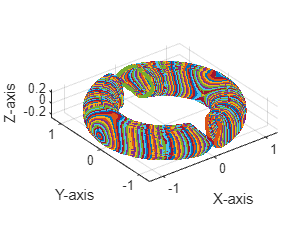

% Plot the manifold in 3D space
figure
for curN=1:curveNumTrain
scatter3(Xtrain{curN}(1,:), Xtrain{curN}(2,:), Xtrain{curN}(3,:),'.');hold on
end
for curN=1:curveNumTest
scatter3(Xtest{curN}(1,:), Xtest{curN}(2,:), Xtest{curN}(3,:),'.');hold on
end

grid on;hold off
axis equal; % Make sure the aspect ratio is the same for all axes
xlabel('X-axis');
ylabel('Y-axis');
zlabel('Z-axis');

## 2 SINDy model building

Prepare the tangent and normal space for training

Pn=sum(Pnum);
knear=round(Pn^0.5/2);
lambda=1e-2;

Tbox_ideal={};Ttrain_ideal={};
Nbox_ideal={};Ntrain_ideal={};
Xangle={};
T_tensor=zeros(d,n,Pn);
% Tbox_imp={};
% Nbox_imp={};
count=1;
for curN=1:curveNumNoSglP
    for i=1:Pnum(curN)
        [Tbox_ideal{curN,i},Nbox_ideal{curN,i}]=TNspace_TorusConstW_Ideal(Xsp{curN}(:,i), R, r);
        T_tensor(:,:,count)=Tbox_ideal{curN,i}';
        count=count+1;
    end
end

count=1;
for curN=trainIndex
Ttrain_ideal{count}=Tbox_ideal(curN,:);
Ntrain_ideal{count}=Nbox_ideal(curN,:);
count=count+1;
end

% TtrainBox={};
% count=1;
% for curN=trainIndex
%     for i=1:Pnum(curN)-1% do not consider the last point of each curve to cooperate with 1st-order finite diff dotX matrix
%     [Ti,Ni]=TNspace_TorusConstW_Ideal(Xsp{curN}(:,i), R, r);
%     TtrainBox{count}=Ti;
%     count=count+1;
%     end
% end

count=1;
for curN=testIndex
Ttest{curN}=Tbox_ideal(curN,:);
Ntest{curN}=Nbox_ideal(curN,:);
count=count+1;
end

Solve the GeoSINDy model

The essence of GSINDy is using a projection to correct the numerical error of dotx. 

Also, the GSINDy method giving a way to tolerance noise by considering the knear points to estimate the tangent space and dotx.

Numtrain=0;
for i=trainIndex
Numtrain=Numtrain+Pnum(i);% number of points in training set
end

dotX_trainMatrix=zeros(Numtrain,n);
library_trainMatrix=[];

dotXtrain={};dotXtrain_T_amb={};
count=1;countT=1;
TtrainBox={};
for curN=trainIndex
    PreStepMatrix=Xsp{curN};
    NextStepMatrix=Xsp{curN};
    PreStepMatrix(:,end)=[];
    NextStepMatrix(:,1)=[];
    dotXtrain{count}=(NextStepMatrix-PreStepMatrix)/Dt;%forward first order approximate
    
    for i=1:size(Xsp{curN},2)-1    
        T=Tbox_ideal{curN,i};
        dotXtrain_T_amb{count}(:,i)=T*pinv(T'*T)*T'*dotXtrain{count}(:,i);
        TtrainBox{countT}=T;
        countT=countT+1;
    end
    count=count+1;
end

dotXtrainTambMatrix=[];
for i=1:size(dotXtrain_T_amb,2)
    dotXtrainTambMatrix=[dotXtrainTambMatrix dotXtrain_T_amb{i}];
end
dotXtrainTambMatrix=dotXtrainTambMatrix';

XtrainMatrix=[];
for curN=trainIndex
    XtrainMatrix=[XtrainMatrix Xsp{curN}(:,1:end-1)];%pay attention, to make sure it coincide with 1st-order diff dotX, we do not consider the last point of each curve
end

% time variant candidate function
% polyorder=4;
% usesine=1;
% t_step=0;
% for i=1:size(XtrainMatrix,2)
%     curveIniP=floor(i/Pnum)*Pnum+1;
%     library_trainMatrix(i,:)=real(CandidateFunVector(t_step,XtrainMatrix(:,i)',XtrainMatrix(:,curveIniP)',n,polyorder,usesine));% only first curve for training
%     t_step=t_step+Dt;
% end

% poly-order time invariant model
polyorder=5;
usesine=0;
library_trainMatrix=CandidateFunVectorOriPolySine([],XtrainMatrix',n,polyorder,usesine);

Coef_GeomSINDy = sparsifyDynamics_modify(TtrainBox,library_trainMatrix,dotXtrainTambMatrix,lambda,n)

Coef_GeomSINDy = 1.0e+03 *

    0.0000         0         0
   -0.0361         0    0.0001
   -0.0000   -0.0363   -0.0005
   -0.0001   -0.0005    0.0369
   -0.0001         0         0
         0         0   -0.0005
         0    0.0001         0
   -0.0001         0         0
    0.0014         0         0
    0.0001         0         0


% Coef_GeomSINDy = sparsifyDynamics(library_trainMatrix,dotXtrainTambMatrix,lambda,n)

GSINDy model build fmincon version

% polyorder=5;
% usesine=0;
% polyTermNum=size(generatemultiindex(polyorder,n),2);
% 
% A = []; % 线性不等式约束系数
% b = []; % 线性不等式约束边界
% Aeq = []; % 线性等式约束系数
% beq = []; % 线性等式约束边界
% lb = -100*ones(polyTermNum*n,1); % 变量的下界
% ub = 100*ones(polyTermNum*n,1); % 变量的上界
% decisionV0=0.1*ones(polyTermNum*n,1);
% options = optimoptions('fmincon', 'Algorithm', 'interior-point');
% 
% [optOut, fval] = fmincon(@(decisionV) GSINDy_training_Proj_version(decisionV,dotXtrainTambMatrix,XtrainMatrix,TtrainBox,polyTermNum,polyorder,usesine,1), decisionV0, A, b, Aeq, beq, lb, ub,[],options);
% Coef_GeomSINDy=reshape(optOut,polyTermNum,n)
% Coef_GeomSINDy(Coef_GeomSINDy<lambda)=0

Solve the SINDy model

dotX_trainMatrix=zeros(Numtrain,n);

dotXtrainMatrix=[];
for i=1:size(dotXtrain,2)
    dotXtrainMatrix=[dotXtrainMatrix dotXtrain{i}];
end
dotXtrainMatrix=dotXtrainMatrix';

Coef_SINDy = sparsifyDynamics(library_trainMatrix,dotXtrainMatrix,lambda,n)

Coef_SINDy =          0   -0.0102         0
    1.5659         0   -0.0248
   -0.0153    1.7865    0.1058
    0.1100    0.9769    0.2078
         0    0.0248         0
         0         0   -0.9829
         0   -0.1689         0
         0    0.0249         0
    1.0569         0         0
         0   -0.0324         0


## 3 Prediction 

#### Purely prediction without correction algorithm in each step

Predict a trajectory traveling on the manifold **only given the initial points**.

GeoSINDy model:

XpreGSINDy={};
XpreGSINDy_NC={};
error_GeoSINDy={};
error_GeoSINDy_NC={};

Ti=[];
see={};

tspanPre=0:Dt:t_total*timeMulti-Dt;

curveTest=[2 4 6 8 22 24 26 28 42 44 46 48 62 64 66 68];
% curveTest=2;
curN=1;
for Round=curveTest
XpreGMLStest{curN}=zeros(size(Xtest{Round}));
XpreGMLStest{curN}(:,1)=Xtest{Round}(:,1);

XpreGSINDy{curN}=zeros(size(Xtest{Round}));
XpreGSINDy{curN}(:,1)=Xtest{Round}(:,1);%+0.002*randn(size(X(:,1:1+shiftStr)));

XpreGSINDy_NC{curN}=zeros(size(Xtest{Round}));
XpreGSINDy_NC{curN}(:,1)=Xtest{Round}(:,1);

XpreGSINDy_NC_RK2{curN}=zeros(size(Xtest{Round}));
XpreGSINDy_NC_RK2{curN}(:,1)=Xtest{Round}(:,1);

XpreGSINDy_ode45{curN}=zeros(size(Xtest{Round}));
XpreGSINDy_ode45{curN}(:,1)=Xtest{Round}(:,1);

XpreGSINDy_ode45NC{curN}=zeros(size(Xtest{Round}));
XpreGSINDy_ode45NC{curN}(:,1)=Xtest{Round}(:,1);

nodes=size(Xtest{curN},2);% The same time length for all curve (at leaset 1 cycle of the biggest curve)
% nodes=1000;

degr=4;% GMLS parameter

error_GeoSINDy{curN}=zeros(1,nodes);
errorOffManifold_GeoSINDy{curN}=zeros(1,nodes);

error_GeoSINDy_NC{curN}=zeros(1,nodes);
errorOffManifold_GeoSINDy_NC{curN}=zeros(1,nodes);

%% ==============GMLS with ideal input test==============
    for i=1:nodes-1
    dx=Xtest{Round}(:,i+1)-XpreGMLStest{curN}(:,i);
    [Ti,Ni]=TNspace_TorusConstW_Ideal(XpreGMLStest{curN}(:,i), R, r);
    dxT=Ti*Ti'*dx;
    searchPool=Xsp_Together;
    [~,indices] = knnCPU(searchPool',XpreGMLStest{curN}(:,i)',knear);%only use 1/20 time of knnsearch
    DistPoint=searchPool(:,indices);
    Dist=DistPoint-XpreGMLStest{curN}(:,i);
    dXN_n=GMLS_for_VerticalInc(Dist,Ti,Ni,dxT,degr,knear,d);
    XpreGMLStest{curN}(:,i+1)=XpreGMLStest{curN}(:,i)+dxT+dXN_n;
    end

%% =============================GSINDy Euler solver=============
    for i=1:nodes-1
    xi_NC=XpreGSINDy_NC{curN}(:,i);
    ti=tspanPre(1,i);

    [Ti,Ni]=TNspace_TorusConstW_Ideal(xi_NC, R, r);
    Pi=Ti*pinv(Ti'*Ti)*Ti';
    dotXT=1*(CandidateFunVectorOriPolySine(ti,xi_NC',n,polyorder,usesine)*Coef_GeomSINDy)';
    dotXT=Pi*dotXT;

    queryPoint=xi_NC';
    searchPool=Xsp_Together;
    [~,indices] = knnCPU(searchPool',queryPoint,knear);%only use 1/20 time of knnsearch
    DistPoint=searchPool(:,indices);
    Dist=DistPoint-queryPoint';
    
    % ==========GMLS Euler-NC prof H version=========
    % P_tilde=Ti*pinv(Ti'*Ti)*Ti';
    % [U2,S2,~] = svd(P_tilde);
    % [~,IX2] = sort(diag(S2),'descend');
    % U2 = U2(:,IX2); % eigenvector
    % tvec = U2; 
    % [iota] = GMLSparam(Dist',tvec,degr,d,xi',(xi+Dt*dotXT)');
    % XpreGSINDy_NC{curN}(:,i+1)=iota';

    % ===========GMLS Euler-NC my version==========(Eular-based most basic gmls version)
    t1=Dt*1;
    dXN_n1=GMLS_for_VerticalInc(Dist,Ti,Ni,dotXT*t1,degr,knear,d);
    Xnext_hat1=XpreGSINDy_NC{curN}(:,i)+dotXT*t1+dXN_n1;
    XpreGSINDy_NC{curN}(:,i+1)=Xnext_hat1;
    
    % ===========GMLS prediction-correction RK2 version==========
    dotXT1=(CandidateFunVectorOriPolySine(t1,Xnext_hat1',n,polyorder,usesine)*Coef_GeomSINDy)'; 
    [Tnext,Nnext]=TNspace_TorusConstW_Ideal(Xnext_hat1, R, r);
    Pnext=Tnext*pinv(Tnext'*Tnext)*Tnext';
    dotXT1=Pnext*dotXT1;
    XpreGSINDy_NC_RK2{curN}(:,i+1)=XpreGSINDy_NC_RK2{curN}(:,i)+(dotXT+dotXT1)/2*Dt;
    
    % ==========non-correction version===========
    xi=XpreGSINDy{curN}(:,i);
    dotXT=1*(CandidateFunVectorOriPolySine(ti,xi',n,polyorder,usesine)*Coef_GeomSINDy)';
    [Ti,Ni]=TNspace_TorusConstW_Ideal(xi, R, r);
    Pi=Ti*pinv(Ti'*Ti)*Ti';
    dotXT=Pi*dotXT;
    XpreGSINDy{curN}(:,i+1)=XpreGSINDy{curN}(:,i)+dotXT*Dt;
    end

%% ===========================GSINDy ode45 solver=============
    % basic version
    X0=XpreGSINDy_ode45{curN}(:,1);%[x0;y0;z0];
    % matlab function
    [t, Xsol] = ode45(@(t, X) dotX_GSINDy_odeSolver(t,X,n,polyorder,usesine,Coef_GeomSINDy, R, r),tspanPre,X0,options_ode);
    Xsol = interp1(t, Xsol, tspanPre', 'pchip');
    XpreGSINDy_ode45{curN}=Xsol';

    % NC version
    % for i=1:nodes-1
    % xi=XpreGSINDy_ode45NC{curN}(:,i);
    % ti=tspanPre(1,i);
    % dotX=(CandidateFunVectorIdeal(ti,xi,R,r,w_theta,theta0(1,curN),w_phi,phi0(1,curN),mode)*Coef_IdlGeomSINDy)';
    % 
    % xi1=xi+0.5*Dt*dotX;
    % ti1=ti+0.5*Dt;
    % dotX1=(CandidateFunVectorIdeal(ti1,xi1,R,r,w_theta,theta0(1,curN),w_phi,phi0(1,curN),mode)*Coef_IdlGeomSINDy)';
    % 
    % xi2=xi+0.5*Dt*dotX1;
    % ti2=ti+0.5*Dt;
    % dotX2=(CandidateFunVectorIdeal(ti2,xi2,R,r,w_theta,theta0(1,curN),w_phi,phi0(1,curN),mode)*Coef_IdlGeomSINDy)';
    % 
    % xi3=xi+Dt*dotX2;
    % ti3=ti+Dt;
    % dotX3=(CandidateFunVectorIdeal(ti3,xi3,R,r,w_theta,theta0(1,curN),w_phi,phi0(1,curN),mode)*Coef_IdlGeomSINDy)';
    % 
    % dx=Dt/6*(dotX+dotX1*2+dotX2*2+dotX3);
    % [Ti,Ni]=TNspace_TorusConstW_Ideal(xi, R, r);
    % dxT=Ti*Ti'*dx;
    % searchPool=Xsp_Together;
    % [~,indices] = knnCPU(searchPool',xi',knear);%only use 1/20 time of knnsearch
    % DistPoint=searchPool(:,indices);
    % Dist=DistPoint-xi;
    % dXN_n=GMLS_for_VerticalInc(Dist,Ti,Ni,dxT,degr,knear,d);
    % XpreGSINDy_ode45NC{curN}(:,i+1)=XpreGSINDy_ode45NC{curN}(:,i)+dxT+dXN_n; 
    % end
% ===================================================
    % GMLS ideal input test error reord
    error_GMLStest{curN}=vecnorm(XpreGMLStest{curN}-Xtest_total{Round}(:,1:length(tspanPre)))/r;
    for i=1:size(XpreGMLStest{curN},2)
    [errorOffManifold_GMLStest{curN}(i),~]=OffTorusError(real(XpreGMLStest{curN}(:,i)),R,r);
    end

    e_max=max(error_GeoSINDy{curN});
    eOffMan_max=max(errorOffManifold_GeoSINDy{curN});
    
    % Euler error record
    error_GeoSINDy{curN}=vecnorm(XpreGSINDy{curN}-Xtest_total{Round}(:,1:length(tspanPre)))/r;
    for i=1:size(XpreGSINDy{curN},2)
    [errorOffManifold_GeoSINDy{curN}(i),~]=OffTorusError(real(XpreGSINDy{curN}(:,i)),R,r);
    end

    e_max=max(error_GeoSINDy{curN});
    eOffMan_max=max(errorOffManifold_GeoSINDy{curN});
    
    % Euler-NC error record
    error_GeoSINDy_NC{curN}=vecnorm(XpreGSINDy_NC{curN}-Xtest_total{Round}(:,1:length(tspanPre)))/r;
    for i=1:size(XpreGSINDy_NC{curN},2)
    [errorOffManifold_GeoSINDy_NC{curN}(i),~]=OffTorusError(real(XpreGSINDy_NC{curN}(:,i)),R,r);
    end

    e_max_NC=max(error_GeoSINDy_NC{curN});
    eOffMan_max_NC=max(errorOffManifold_GeoSINDy_NC{curN});

    % Euler-NC-RK2 error record
    error_GeoSINDy_NC_RK2{curN}=vecnorm(XpreGSINDy_NC_RK2{curN}-Xtest_total{Round}(:,1:length(tspanPre)))/r;
    for i=1:size(XpreGSINDy_NC_RK2{curN},2)
    [errorOffManifold_GeoSINDy_NC_RK2{curN}(i),~]=OffTorusError(real(XpreGSINDy_NC_RK2{curN}(:,i)),R,r);
    end

    e_max_NC_RK2=max(error_GeoSINDy_NC_RK2{curN});
    eOffMan_max_NC_RK2=max(errorOffManifold_GeoSINDy_NC_RK2{curN});

    % ode45 error record
    error_GeoSINDy_ode45{curN}=vecnorm(XpreGSINDy_ode45{curN}-Xtest_total{Round}(:,1:length(tspanPre)))/r;
    for i=1:size(XpreGSINDy_ode45{curN},2)
    [errorOffManifold_GeoSINDy_ode45{curN}(i),~]=OffTorusError(real(XpreGSINDy_ode45{curN}(:,i)),R,r);
    end

    e_max_ode45=max(error_GeoSINDy_ode45{curN});
    eOffMan_max_ode45=max(errorOffManifold_GeoSINDy_ode45{curN});

    % ode45-NC error record
    % error_GeoSINDy_ode45NC{curN}=vecnorm(XpreGSINDy_ode45NC{curN}-Xtest_total{curN}(:,1:length(tspanPre)))/r;
    % for i=1:size(XpreGSINDy_ode45NC{curN},2)
    % [errorOffManifold_GeoSINDy_ode45NC{curN}(i),~]=OffTorusError(real(XpreGSINDy_ode45NC{curN}(:,i)),R,r);
    % end
    % 
    % e_max_ode45NC=max(error_GeoSINDy_ode45NC{curN});
    % eOffMan_max_ode45NC=max(errorOffManifold_GeoSINDy_ode45NC{curN});

fig=0;
if fig==1
figure
plot3(XpreGMLStest{curN}(1,1:nodes), XpreGMLStest{curN}(2,1:nodes), XpreGMLStest{curN}(3,1:nodes),'.','Linewidth', 0.1);
title(sprintf('GSINDy-GMLStest prediction curN%d', curN))
hold on
plot3(Xtest_total{Round}(1,1:nodes), Xtest_total{Round}(2,1:nodes), Xtest_total{Round}(3,1:nodes),'.','Linewidth', 5);legend('esti-curve','sample-curve')
hold off
xlabel('x');ylabel('y');zlabel('z')

figure
plot3(XpreGSINDy{curN}(1,1:nodes), XpreGSINDy{curN}(2,1:nodes), XpreGSINDy{curN}(3,1:nodes),'.','Linewidth', 0.1);
title(sprintf('GSINDy-Euler prediction curN%d', curN))
hold on
plot3(Xtest_total{Round}(1,1:nodes), Xtest_total{Round}(2,1:nodes), Xtest_total{Round}(3,1:nodes),'.','Linewidth', 5);legend('esti-curve','sample-curve')
hold off
xlabel('x');ylabel('y');zlabel('z')

figure
plot3(XpreGSINDy_NC{curN}(1,1:nodes), XpreGSINDy_NC{curN}(2,1:nodes), XpreGSINDy_NC{curN}(3,1:nodes),'.','Linewidth', 0.1);
title(sprintf('GSINDy-EulerNC prediction curN%d', curN))
hold on
plot3(Xtest_total{Round}(1,1:nodes), Xtest_total{Round}(2,1:nodes), Xtest_total{Round}(3,1:nodes),'.','Linewidth', 5);legend('esti-curve','sample-curve')
hold off
xlabel('x');ylabel('y');zlabel('z')

figure
plot3(XpreGSINDy_NC_RK2{curN}(1,1:nodes), XpreGSINDy_NC_RK2{curN}(2,1:nodes), XpreGSINDy_NC_RK2{curN}(3,1:nodes),'.','Linewidth', 0.1);
title(sprintf('GSINDy-EulerNC-RK2 prediction curN%d', curN))
hold on
plot3(Xtest_total{Round}(1,1:nodes), Xtest_total{Round}(2,1:nodes), Xtest_total{Round}(3,1:nodes),'.','Linewidth', 5);legend('esti-curve','sample-curve')
hold off
xlabel('x');ylabel('y');zlabel('z')

figure
plot3(XpreGSINDy_ode45{curN}(1,1:nodes), XpreGSINDy_ode45{curN}(2,1:nodes), XpreGSINDy_ode45{curN}(3,1:nodes),'.','Linewidth', 0.1);
title(sprintf('GSINDy-ode45 prediction curN%d', curN))
hold on
plot3(Xtest_total{Round}(1,1:nodes), Xtest_total{Round}(2,1:nodes), Xtest_total{Round}(3,1:nodes),'.','Linewidth', 5);legend('esti-curve','sample-curve')
hold off
xlabel('x');ylabel('y');zlabel('z')

% figure
% plot3(XpreGSINDy_ode45NC{curN}(1,1:nodes), XpreGSINDy_ode45NC{curN}(2,1:nodes), XpreGSINDy_ode45NC{curN}(3,1:nodes),'.','Linewidth', 0.1);
% title(sprintf('GSINDy-ode45NC prediction curN%d', curN))
% hold on
% plot3(Xtest_total{curN}(1,1:nodes), Xtest_total{curN}(2,1:nodes), Xtest_total{curN}(3,1:nodes),'.','Linewidth', 5);legend('esti-curve','sample-curve')
% hold off
% xlabel('x');ylabel('y');zlabel('z')
end
curN=curN+1;
end

SINDy model:

XpreSINDy={};
errorOnly_SINDy={};
curN=1;
for Round=curveTest
XpreSINDy{curN}=zeros(size(Xtest{curN}));
XpreSINDy{curN}(:,1)=Xtest{Round}(:,1);%+0.002*randn(size(X(:,1:1+shiftStr)));

nodes=size(Xtest{Round},2);% The same time length for all curve (at leaset 1 cycle of the biggest curve)

errorOnly_SINDy{curN}=zeros(1,nodes);
errorOffManifoldOnly_SINDy{curN}=zeros(1,nodes);

% ====================1st order Euler===================
% for i=1:length(tspanPre)-1%Pnum-1
%     xi=XpreSINDy{curN}(:,i);
%     ti=tspanPre(1,i);
%     dXpDt=(CandidateFunVectorIdeal(ti,xi,R,r,w_theta,theta0(1,curN),w_phi,phi0(1,curN),mode)*Coef_IdlSINDy)';
%     XpreSINDy{curN}(:,i+1)=XpreSINDy{curN}(:,i)+dXpDt*Dt;
% end
% ========================================================

% ===================ode45================================
X0=XpreSINDy{curN}(:,1);
[t, Xsol] = ode45(@(t, X) (CandidateFunVectorOriPolySine(t,X',n,polyorder,usesine)*Coef_SINDy)',tspanPre,X0,options_ode);
Xsol = interp1(t, Xsol, tspanPre', 'pchip');
XpreSINDy{curN}=Xsol';
% ========================================================

errorOnly_SINDy{curN}=vecnorm((XpreSINDy{curN}-Xtest_total{Round}(:,1:size(XpreSINDy{curN},2))),2)/r;
for i=1:size(XpreSINDy{curN},2)
[errorOffManifoldOnly_SINDy{curN}(i),~]=OffTorusError(real(XpreSINDy{curN}(:,i)),R,r);
end

e_max=max(errorOnly_SINDy{curN});
eOffMan_max=max(errorOffManifoldOnly_SINDy{curN});

fig=0;
if fig==1
figure
plot3(XpreSINDy{curN}(1,1:nodes), XpreSINDy{curN}(2,1:nodes), XpreSINDy{curN}(3,1:nodes),'.','Linewidth', 0.1);
title(sprintf('SINDy prediction curN%d', curN))
hold on
plot3(Xtest_total{curN}(1,1:nodes), Xtest_total{curN}(2,1:nodes), Xtest_total{curN}(3,1:nodes),'.','Linewidth', 5);legend('esti-curve','sample-curve')
hold off
figure
plot3(XpreSINDy{curN}(1,1:nodes), XpreSINDy{curN}(2,1:nodes), XpreSINDy{curN}(3,1:nodes));title('prediction performance')
figure
plot(errorOnly_SINDy{curN}(1,1:nodes));title('relative error for each step')
end
curN=curN+1;
end

## 4 Performance comparing

#### off manifold error

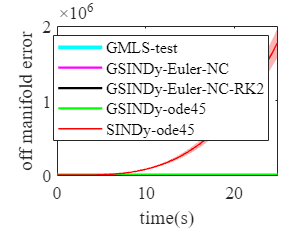

errorTN_SINDy1_GMLStest=errorOffManifold_GMLStest;

errorTN_SINDy1=errorOffManifold_GeoSINDy;

errorTN_SINDy1_NC=errorOffManifold_GeoSINDy_NC;

errorTN_SINDy1_NC_RK2=errorOffManifold_GeoSINDy_NC_RK2;

errorTN_SINDy1_ode45=errorOffManifold_GeoSINDy_ode45;

% errorTN_SINDy1_ode45NC=errorOffManifold_GeoSINDy_ode45NC;

errorOnly_SINDy1=errorOffManifoldOnly_SINDy;

%===========GMLS ideal input test
X_ErrorMatrix_GMLStest=zeros(curveNum,size(errorTN_SINDy1_GMLStest{1},2));

for curN=1:length(curveTest)
X_ErrorMatrix_GMLStest(curN,:)=errorTN_SINDy1_GMLStest{curN};
end

steps=1:1:size(errorTN_SINDy1_GMLStest{curN},2);
if size(X_ErrorMatrix_GMLStest,1)==1
X_AveError_GMLStest=X_ErrorMatrix_GMLStest*100;
else
X_AveError_GMLStest=mean(X_ErrorMatrix_GMLStest)*100;
end

%===========Euler GSINDy
X_ErrorMatrix=zeros(curveNum,size(errorTN_SINDy1{1},2));
for curN=1:length(curveTest)
X_ErrorMatrix(curN,:)=errorTN_SINDy1{curN};
end

steps=1:1:size(errorTN_SINDy1{curN},2);
if size(X_ErrorMatrix,1)==1
X_AveError=X_ErrorMatrix*100;
else
X_AveError=mean(X_ErrorMatrix)*100;
end

%===========Euler-NC GSINDy
X_ErrorMatrix_NC=zeros(curveNum,size(errorTN_SINDy1_NC{1},2));
for curN=1:length(curveTest)
X_ErrorMatrix_NC(curN,:)=errorTN_SINDy1_NC{curN};
end

steps=1:1:size(errorTN_SINDy1_NC{curN},2);
if size(X_ErrorMatrix_NC,1)==1
X_AveError_NC=X_ErrorMatrix_NC*100;
else
X_AveError_NC=mean(X_ErrorMatrix_NC)*100;
end

%===========Euler-NC-RK2 GSINDy
X_ErrorMatrix_NC_RK2=zeros(curveNum,size(errorTN_SINDy1_NC_RK2{1},2));
for curN=1:length(curveTest)
X_ErrorMatrix_NC_RK2(curN,:)=errorTN_SINDy1_NC_RK2{curN};
end

steps=1:1:size(errorTN_SINDy1_NC_RK2{curN},2);
if size(X_ErrorMatrix_NC_RK2,1)==1
X_AveError_NC_RK2=X_ErrorMatrix_NC_RK2*100;
else
X_AveError_NC_RK2=mean(X_ErrorMatrix_NC_RK2)*100;
end

%============ode45 GSINDy
X_ErrorMatrix_ode45=zeros(curveNum,size(errorTN_SINDy1_ode45{1},2));
for curN=1:length(curveTest)
X_ErrorMatrix_ode45(curN,:)=errorTN_SINDy1_ode45{curN};
end

steps=1:1:size(errorTN_SINDy1_ode45{curN},2);
if size(X_ErrorMatrix_ode45,1)==1
X_AveError_ode45=X_ErrorMatrix_ode45*100;
else
X_AveError_ode45=mean(X_ErrorMatrix_ode45)*100;
end

%============ode45-NC GSINDy
% X_ErrorMatrix_ode45NC=zeros(curveNum,size(errorTN_SINDy1_ode45NC{1},2));
% 
% for curN=1:curveNumTest
% X_ErrorMatrix_ode45NC(curN,:)=errorTN_SINDy1_ode45NC{curN};
% end
% 
% steps=1:1:size(errorTN_SINDy1_ode45NC{curN},2);
% if size(X_ErrorMatrix_ode45NC,1)==1
% X_AveError_ode45NC=X_ErrorMatrix_ode45NC*100;
% else
% X_AveError_ode45NC=mean(X_ErrorMatrix_ode45NC)*100;
% end

%===========ode45(Euler/ode45) SINDy
X_ErrorMatrixOnlySINDy=zeros(curveNum,size(errorOnly_SINDy1{1},2));
for curN=1:length(curveTest)
X_ErrorMatrixOnlySINDy(curN,:)=errorOnly_SINDy1{curN};
end

steps=1:1:size(errorOnly_SINDy1{curN},2);
time=(steps-1)*2*Dt;

if size(X_ErrorMatrixOnlySINDy,1)==1
X_AveErrorOnlySINDy=X_ErrorMatrixOnlySINDy*100;
else
X_AveErrorOnlySINDy=mean(X_ErrorMatrixOnlySINDy)*100;
end

figure%relative error sample 
f_upper=X_AveError_GMLStest+std(X_ErrorMatrix_GMLStest);f_lower=X_AveError_GMLStest-std(X_ErrorMatrix_GMLStest);
plot(time,X_AveError_GMLStest, 'LineWidth', 2.5,'Color','cyan');hold on;
fill([time fliplr(time)], [f_upper fliplr(f_lower)], 'cyan', 'FaceAlpha', 0.3, 'EdgeColor', 'none');hold on;

% f_upper=X_AveError+std(X_ErrorMatrix);f_lower=X_AveError-std(X_ErrorMatrix);
% plot(time,X_AveError, 'LineWidth', 1.5,'Color','blue');hold on;
% fill([time fliplr(time)], [f_upper fliplr(f_lower)], 'blue', 'FaceAlpha', 0.3, 'EdgeColor', 'none');hold on;

f_upper=X_AveError_NC+std(X_ErrorMatrix_NC);f_lower=X_AveError_NC-std(X_ErrorMatrix_NC);
plot(time,X_AveError_NC ,'LineWidth', 1.5,'Color','mag');hold on;
fill([time fliplr(time)], [f_upper fliplr(f_lower)], 'mag', 'FaceAlpha', 0.3, 'EdgeColor', 'none');hold on;

f_upper=X_AveError_NC_RK2+std(X_ErrorMatrix_NC_RK2);f_lower=X_AveError_NC_RK2-std(X_ErrorMatrix_NC_RK2);
plot(time,X_AveError_NC_RK2 ,'LineWidth', 1.5,'Color','black');hold on;
fill([time fliplr(time)], [f_upper fliplr(f_lower)], 'black', 'FaceAlpha', 0.3, 'EdgeColor', 'none');hold on;

f_upper=X_AveError_ode45+std(X_ErrorMatrix_ode45);f_lower=X_AveError_ode45-std(X_ErrorMatrix_ode45);
plot(time,X_AveError_ode45 ,'LineWidth', 1.5,'Color','green');hold on;
fill([time fliplr(time)], [f_upper fliplr(f_lower)], 'green', 'FaceAlpha', 0.3, 'EdgeColor', 'none');hold on;

% f_upper=X_AveError_ode45NC+std(X_ErrorMatrix_ode45NC);f_lower=X_AveError_ode45NC-std(X_ErrorMatrix_ode45NC);
% plot(time,X_AveError_ode45NC ,'LineWidth', 1.5,'Color','black');hold on;
% fill([time fliplr(time)], [f_upper fliplr(f_lower)], 'black', 'FaceAlpha', 0.3, 'EdgeColor', 'none');hold on;

f_upper=X_AveErrorOnlySINDy+std(X_ErrorMatrixOnlySINDy);f_lower=X_AveErrorOnlySINDy-std(X_ErrorMatrixOnlySINDy);
plot(time,X_AveErrorOnlySINDy, 'LineWidth', 1,'Color','red');hold on;
fill([time fliplr(time)], [f_upper fliplr(f_lower)], 'red', 'FaceAlpha', 0.3, 'EdgeColor', 'none');hold off;

xlabel('time(s)');ylabel('off manifold error');
% legend('GMLS-test','','GSINDy-Euler','','GSINDy-Euler-NC','','GSINDy-Euler-NC-RK2','','GSINDy-ode45','','SINDy-ode45')
legend('GMLS-test','','GSINDy-Euler-NC','','GSINDy-Euler-NC-RK2','','GSINDy-ode45','','SINDy-ode45')
% legend('GMLS-test','','GSINDy-Euler','','GSINDy-Euler-NC','','GSINDy-ode45','','SINDy-ode45')
% legend('GMLS-test','','GSINDy','','GSINDy-NC','','GSINDy ode45','','GSINDy ode45-NC','','SINDy')
% legend('GMLS-test','','GSINDy-Euler-NC','','GSINDy-ode45','','SINDy-ode45')
% legend('GSINDy','','GSINDy-NC','','GSINDy ode45','','SINDy')
set(gca, 'FontName', 'Times New Roman', 'FontSize', frontsize);xlim([0,time(end)])

% set(gca, 'YScale', 'log')

#### norm2 error

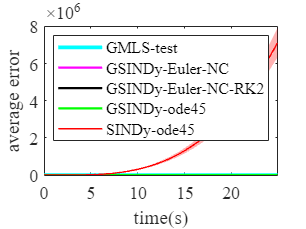

errorTN_SINDy2_GMLStest=error_GMLStest;

errorTN_SINDy2=error_GeoSINDy;

errorTN_SINDy2_NC=error_GeoSINDy_NC;

errorTN_SINDy2_NC_RK2=error_GeoSINDy_NC_RK2;

errorTN_SINDy2_ode45=error_GeoSINDy_ode45;

% errorTN_SINDy2_ode45NC=error_GeoSINDy_ode45NC;

errorOnly_SINDy2=errorOnly_SINDy;

%===========GMLS ideal input test
X_ErrorMatrix_GMLStest=zeros(curveNum,size(errorTN_SINDy2_GMLStest{1},2));
for curN=1:length(curveTest)
X_ErrorMatrix_GMLStest(curN,:)=errorTN_SINDy2_GMLStest{curN};
end

steps=1:1:size(errorTN_SINDy2_GMLStest{curN},2);

if size(X_ErrorMatrix_GMLStest,1)==1
X_AveError_GMLStest=X_ErrorMatrix_GMLStest*100;
else
X_AveError_GMLStest=mean(X_ErrorMatrix_GMLStest)*100;
end

%=================Euler GSINDy
X_ErrorMatrix=zeros(curveNum,size(errorTN_SINDy2{1},2));
for curN=1:length(curveTest)
X_ErrorMatrix(curN,:)=errorTN_SINDy2{curN};
end

steps=1:1:size(errorTN_SINDy2{curN},2);

if size(X_ErrorMatrix,1)==1
X_AveError=X_ErrorMatrix*100;
else
X_AveError=mean(X_ErrorMatrix)*100;
end

%==================Euler-NC GSINDy
X_ErrorMatrix_NC=zeros(curveNum,size(errorTN_SINDy2_NC{1},2));
for curN=1:length(curveTest)
X_ErrorMatrix_NC(curN,:)=errorTN_SINDy2_NC{curN};
end

steps=1:1:size(errorTN_SINDy2_NC{curN},2);

if size(X_ErrorMatrix_NC,1)==1
X_AveError_NC=X_ErrorMatrix_NC*100;
else
X_AveError_NC=mean(X_ErrorMatrix_NC)*100;
end

%==================Euler-NC-RK2 GSINDy
X_ErrorMatrix_NC_RK2=zeros(curveNum,size(errorTN_SINDy2_NC_RK2{1},2));
for curN=1:length(curveTest)
X_ErrorMatrix_NC_RK2(curN,:)=errorTN_SINDy2_NC_RK2{curN};
end

steps=1:1:size(errorTN_SINDy2_NC_RK2{curN},2);

if size(X_ErrorMatrix_NC_RK2,1)==1
X_AveError_NC_RK2=X_ErrorMatrix_NC_RK2*100;
else
X_AveError_NC_RK2=mean(X_ErrorMatrix_NC_RK2)*100;
end

%==================ode45 GSINDy
X_ErrorMatrix_ode45=zeros(curveNum,size(errorTN_SINDy2_ode45{1},2));
for curN=1:length(curveTest)
X_ErrorMatrix_ode45(curN,:)=errorTN_SINDy2_ode45{curN};
end

steps=1:1:size(errorTN_SINDy2_ode45{curN},2);

if size(X_ErrorMatrix_ode45,1)==1
X_AveError_ode45=X_ErrorMatrix_ode45*100;
else
X_AveError_ode45=mean(X_ErrorMatrix_ode45)*100;
end

%==================ode45-NC GSINDy
% X_ErrorMatrix_ode45NC=zeros(curveNum,size(errorTN_SINDy2_ode45NC{1},2));
% 
% for curN=1:curveNumTest
% X_ErrorMatrix_ode45NC(curN,:)=errorTN_SINDy2_ode45NC{curN};
% end
% 
% steps=1:1:size(errorTN_SINDy2_ode45NC{curN},2);
% 
% if size(X_ErrorMatrix_ode45NC,1)==1
% X_AveError_ode45NC=X_ErrorMatrix_ode45NC*100;
% else
% X_AveError_ode45NC=mean(X_ErrorMatrix_ode45NC)*100;
% end

%=================ode45(Euler/ode45) SINDy
X_ErrorMatrixOnlySINDy=zeros(curveNum,size(errorOnly_SINDy2{1},2));
for curN=1:length(curveTest)
X_ErrorMatrixOnlySINDy(curN,:)=errorOnly_SINDy2{curN};
end

steps=1:1:size(errorOnly_SINDy2{curN},2);
time=(steps-1)*2*Dt;

if size(X_ErrorMatrixOnlySINDy,1)==1
X_AveErrorOnlySINDy=X_ErrorMatrixOnlySINDy*100;
else
X_AveErrorOnlySINDy=mean(X_ErrorMatrixOnlySINDy)*100;
end

% frontsize=12;

figure%relative error sample 
f_upper=X_AveError_GMLStest+std(X_ErrorMatrix_GMLStest);f_lower=X_AveError_GMLStest-std(X_ErrorMatrix_GMLStest);
plot(time,X_AveError_GMLStest, 'LineWidth', 2.5,'Color','cyan');hold on;
fill([time fliplr(time)], [f_upper fliplr(f_lower)], 'cyan', 'FaceAlpha', 0.3, 'EdgeColor', 'none');hold on;

% f_upper=X_AveError+std(X_ErrorMatrix);f_lower=X_AveError-std(X_ErrorMatrix);
% plot(time,X_AveError, 'LineWidth', 1.5,'Color','blue');hold on;
% fill([time fliplr(time)], [f_upper fliplr(f_lower)], 'blue', 'FaceAlpha', 0.3, 'EdgeColor', 'none');hold on;

f_upper=X_AveError_NC+std(X_ErrorMatrix_NC);f_lower=X_AveError_NC-std(X_ErrorMatrix_NC);
plot(time,X_AveError_NC, 'LineWidth', 1.5,'Color','mag');hold on;
fill([time fliplr(time)], [f_upper fliplr(f_lower)], 'mag', 'FaceAlpha', 0.3, 'EdgeColor', 'none');hold on;

f_upper=X_AveError_NC_RK2+std(X_ErrorMatrix_NC_RK2);f_lower=X_AveError_NC_RK2-std(X_ErrorMatrix_NC_RK2);
plot(time,X_AveError_NC_RK2, 'LineWidth', 1.5,'Color','black');hold on;
fill([time fliplr(time)], [f_upper fliplr(f_lower)], 'black', 'FaceAlpha', 0.3, 'EdgeColor', 'none');hold on;

f_upper=X_AveError_ode45+std(X_ErrorMatrix_ode45);f_lower=X_AveError_ode45-std(X_ErrorMatrix_ode45);
plot(time,X_AveError_ode45, 'LineWidth', 1.5,'Color','green');hold on;
fill([time fliplr(time)], [f_upper fliplr(f_lower)], 'green', 'FaceAlpha', 0.3, 'EdgeColor', 'none');hold on;

% f_upper=X_AveError_ode45NC+std(X_ErrorMatrix_ode45NC);f_lower=X_AveError_ode45NC-std(X_ErrorMatrix_ode45NC);
% plot(time,X_AveError_ode45NC, 'LineWidth', 1.5,'Color','black');hold on;
% fill([time fliplr(time)], [f_upper fliplr(f_lower)], 'black', 'FaceAlpha', 0.3, 'EdgeColor', 'none');hold on;

f_upper=X_AveErrorOnlySINDy+std(X_ErrorMatrixOnlySINDy);f_lower=X_AveErrorOnlySINDy-std(X_ErrorMatrixOnlySINDy);
plot(time,X_AveErrorOnlySINDy, 'LineWidth', 1.0,'Color','red');hold on;
fill([time fliplr(time)], [f_upper fliplr(f_lower)], 'red', 'FaceAlpha', 0.3, 'EdgeColor', 'none');hold off;

xlabel('time(s)');ylabel('average error');
% legend('GMLS-test','','GSINDy-Euler','','GSINDy-Euler-NC','','GSINDy-Euler-NC-RK2','','GSINDy-ode45','','SINDy-ode45')
legend('GMLS-test','','GSINDy-Euler-NC','','GSINDy-Euler-NC-RK2','','GSINDy-ode45','','SINDy-ode45')
% legend('GMLS-test','','GSINDy-Euler','','GSINDy-Euler-NC','','GSINDy-ode45','','SINDy-ode45')
% legend('GMLS-test','','GSINDy','','GSINDy-NC','','GSINDy ode45','','GSINDy ode45-NC','','SINDy')
% legend('GMLS-test','','GSINDy-Euler-NC','','GSINDy-ode45','','SINDy-ode45')
% legend('GSINDy','','GSINDy-NC','','GSINDy ode45','','SINDy')
set(gca, 'FontName', 'Times New Roman', 'FontSize', frontsize);xlim([0,time(end)])

#### convergence order

Test and record the maximum average error in the time window.

% check the max error
max(X_AveError_GMLStest)/100

ans = 7.7363e-07

max(X_AveError)/100

ans = 0.1728

max(X_AveError_NC)/100

ans = 0.0626

max(X_AveError_NC_RK2)/100

ans = 0.0627

max(X_AveError_ode45)/100

ans = 0.0591

max(X_AveErrorOnlySINDy)/100

ans = 7.1070e+04

Plot curves after finishing record.

% Dt_box=[0.005 0.01 0.05 0.1 0.5];
% e_Dt_curve_GSINDy_Euler=[0.01 0.02 0.0997 0.1991 0.9634];
% % e_Dt_curve_SINDy_Euler=[0.01 0.02 0.0776 0.1550 0.7527];
% e_Dt_curve_GSINDy_Euler_NC=[0.0013 0.0026 0.0129 0.0263 0.0949];
% e_Dt_curve_GSINDy_Euler_NC_RK2=[5.0463e-5 2.0185e-4 0.0050 0.0201 0.4738];
% e_Dt_curve_GSINDy_ode45=[3.3643e-5 1.3457e-4 0.0034 0.0134 0.3400];
% e_Dt_curve_SINDy_ode45=[3.3640e-5 1.3456e-4 0.0660 0.1318 0.6626];
% 
% figure
% loglog(Dt_box,e_Dt_curve_GSINDy_Euler, '--', 'LineWidth', 2);
% hold on
% % loglog(Dt_box,e_Dt_curve_SINDy_Euler, 'LineWidth', 2);
% % hold on
% loglog(Dt_box,e_Dt_curve_GSINDy_Euler_NC, '-.', 'LineWidth', 2);
% hold on
% loglog(Dt_box,e_Dt_curve_GSINDy_Euler_NC_RK2, ':', 'LineWidth', 2);
% hold on
% loglog(Dt_box,e_Dt_curve_GSINDy_ode45, '-', 'LineWidth', 2);
% hold on
% loglog(Dt_box,e_Dt_curve_SINDy_ode45, 'LineWidth', 2);xlabel('step size');ylabel('error');
% xlim([min(Dt_box),max(Dt_box)])
% hold off
% set(gca, 'FontName', 'Times New Roman', 'FontSize', frontsize);
% % legend('GSINDy Euler','SINDy Euler','GSINDy ode45','SINDy ode45','Location','best')
% legend('GSINDy-Euler ','GSINDy-Euler-NC','GSINDy-Euler-NC-RK2','GSINDy-ode45','SINDy-ode45','Location','best')
% 
% coefficients = polyfit(log(Dt_box), log(e_Dt_curve_GSINDy_Euler), 1);
% p_GSINDy_Euler = coefficients(1)
% % coefficients = polyfit(log(Dt_box), log(e_Dt_curve_SINDy_Euler), 1);
% % p_SINDy_Euler = coefficients(1)
% coefficients = polyfit(log(Dt_box), log(e_Dt_curve_GSINDy_Euler_NC), 1);
% p_GSINDy_Euler_NC = coefficients(1)
% coefficients = polyfit(log(Dt_box), log(e_Dt_curve_GSINDy_Euler_NC_RK2), 1);
% p_GSINDy_Euler_NC_RK2 = coefficients(1)
% coefficients = polyfit(log(Dt_box), log(e_Dt_curve_GSINDy_ode45), 1);
% p_GSINDy_ode45 = coefficients(1)
% coefficients = polyfit(log(Dt_box), log(e_Dt_curve_SINDy_ode45), 1);
% p_SINDy_ode45 = coefficients(1)
